**AVD Group 01**

Hanchen Li

Please see **report** for theory and explaination, be aware of the **units** in angle

% House Keeping
clear
clc
close all

g = 9.80665;                          % Standard acceleration of gravity (m/s^2)

Before everything

x_w_l = 21;             % Distance between nosetip to leading edge (m)

Input parameter form Weight and Balance Estimation code

% aftmost CG location (m)
x_CG_aft = 32.7645;
z_CG_aft = -0.4227;
W_CG_aft = 2.3714e5;

x_CG_aft_down = 32.7824;
z_CG_aft_down = -1.2404;
W_CG_aft_down = 2.3714e5;

% foremost CG location (m)
x_CG_for = 31.1027;
z_CG_for = -0.2843;
W_CG_for = 4.0900e5;

x_CG_for_down = 31.1877;
z_CG_for_down = -0.7343;
W_CG_for_down = 4.1700e5;

## **1. Neutral Point**

**Find fuselage coefficient of pitching moment**


x_c_4 = x_w_l + 3.5206; % Wing-root 1/4 chord position (m) % Undefined

L_f = 75.5;             % Total fuselage length (m)

% Find K_f via NACA TR 177

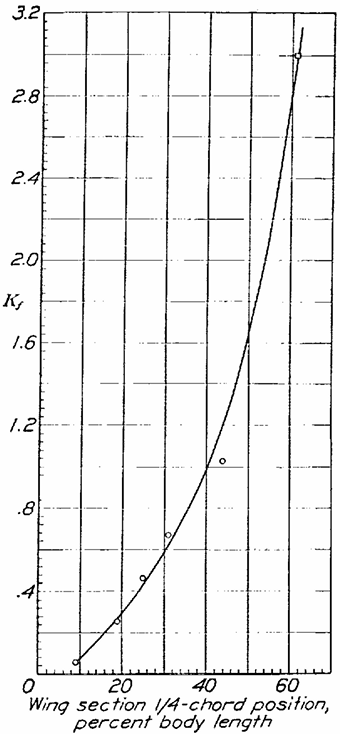


x_c_4 / L_f

ans = 0.3248


K_f = 0.69;          % Undefined

w_f = 6.88;          % Fuselage maximum width (m)

c = 9.84;            % Mean chord length (m) % Undefined

S_w = 639.23;        % Reference wing area (m^2)

d_CM_f = K_f * (L_f * (w_f ^ 2)) / (c * S_w) % (1/rad)

d_CM_f = 0.3920

**Find wing's zero lift pitching moment**

AR = 6.61;              % Aspect Ratio

Sweep = 26.75;          % Wing quarter chord sweep (degree)
Sweep = deg2rad(Sweep); % Wing quarter chord sweep (rad)

twist = 3.9;            % Wing twist (degree)

i_w = -0.1849;          % Wing setting angle (degree)
i_w = deg2rad(i_w);     % Wing setting angle (rad)

C_m_airf_0 = -0.13;     % Incompressible airfoil zero lift pitching moment

d_CL_w_0 = 3.228;       % Incompressible wing lift curve slope (1/rad) % Undefined

% Wing's zero lift pitching moment 'coefficient'
k_C_m0_w = (C_m_airf_0 * (AR * (cos(Sweep) ^ 2)) / (AR + 2 * cos(Sweep)) - 0.01 * twist) / d_CL_w_0

k_C_m0_w = -0.0374

**Other input parameters**

n_h = 0.9;                % Tail efficiency factor

B_w = 64.99;              % Wing span (m)

Taper = 0.20;             % Wing taper ratio

V_S = 50.34;              % Landing stall speed (m/s)

x_ac_w_0 = x_w_l + 11.34; % Wing aerodynamic center at M=0 (m)

x_ac_h_0 = 72.2;          % Wing aerodynamic center at M=0 (m)

h_h = 5.3;                % Vertical distance between wing and horizontal tailplane chord (m)

l_h = x_ac_h_0 - x_ac_w_0; % (m)

S_h = 87.20;              % Horizontal tailplane area (m^2

Notice $Z_t$ is $+\textrm{ve}$ if thrustline under CG

Z_t = -3.3;              % Thrustline above datum (m)

**Find compressible effect on aerodynamic center**

x_ac_M

% x_ac = x_ac_M(x_ac_0, M, S_wing)

**Find downwash derivative**

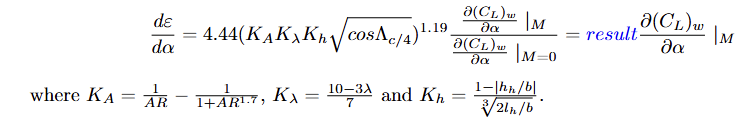

K_A = 1 / AR - 1 / (1 + AR ^ 1.7);

K_Taper = (10 - 3 * Taper) / 7;

K_h = (1 - abs(h_h / B_w)) / ((2 * l_h / B_w) ^ (1 / 3));

% Downwash derivative 'coefficient'
k_d_downwash = (4.44 * (K_A * K_Taper * K_h * (cos(Sweep)) ^ 0.5) ^ 1.19) / d_CL_w_0

k_d_downwash = 0.1131

results


$$x_{\textrm{np}} =\frac{\frac{{d\left(C_L \right)}_W }{d\alpha }{\left(x_{\textrm{ac}} \right)}_w -\frac{{\delta \left(C_M \right)}_f }{\delta \alpha }\bar{c} +\eta_h \frac{{d\left(C_L \right)}_h }{d\alpha }\left(1-\frac{d\varepsilon }{d\alpha }\right)\frac{S_h }{S_w }{\left(x_{\textrm{ac}} \right)}_h }{\frac{{d\left(C_L \right)}_W }{d\alpha }+\eta_h \frac{{d\left(C_L \right)}_h }{d\alpha }\left(1-\frac{d\varepsilon }{d\alpha }\right)\frac{S_h }{S_w }}$$


**0-1** Takeoff **&** **4-5** Missed approach (Takeoff)

[T_TO, c_TO, P_TO, rho_TO] = atmosisa(0);

V_TO = 1.2 * V_S    % Takeoff velocity (m/s)

V_TO = 60.4080


a_0_w_TO = -0.0698;  % Wing takeoff zero lift angle of attack (rad)
d_CL_w_TO = 5.0;  % Wing takeoff lift curve slope (1/rad)

a_0_h_TO = -0.0524;  % Horizontal tailplane takeoff zero lift angle of attack (rad)
d_CL_h_TO = 3.5;  % Horizontal tailplane takeoff lift curve slope (1/rad)

CD_TO = 0.042;       % Takeoff drag coefficient

% No compressibility effect 
x_ac_w_TO = x_ac_w_0

x_ac_w_TO = 32.3400

x_ac_h_TO = x_ac_h_0

x_ac_h_TO = 72.2000


d_downwash_TO = k_d_downwash * d_CL_w_0

d_downwash_TO = 0.3650


C_m0_w_TO = k_C_m0_w * d_CL_w_0

C_m0_w_TO = -0.1206


% Find neutral point
x_np_TO = (d_CL_w_TO * x_ac_w_TO - d_CM_f * c + n_h * d_CL_h_TO * (1 - d_downwash_TO) * (S_h / S_w) * x_ac_h_TO) / ...
    ((d_CL_w_TO + n_h * d_CL_h_TO * (1 - d_downwash_TO) * (S_h / S_w)))

x_np_TO = 33.6711

**2-3** Cruise for an air distance of 7500 nmi at Mach 0.83

[T_c1, c_c1, P_c1, rho_c1] = atmosisa(convlength(28000, 'ft','m'));

V_c1 = 0.83 * c_c1    % 1st cruise velocity (m/s)

V_c1 = 253.8045


a_0_w_c1 = -0.0436;  % Wing 1st cruise zero lift angle of attack (rad)
d_CL_w_c1 = 4.8;  % Wing 1st cruise lift curve slope (1/rad)

a_0_h_c1 = -0.0262;  % Horizontal tailplane 1st cruise zero lift angle of attack (rad)
d_CL_h_c1 = 3.7;  % Horizontal tailplane 1st cruise lift curve slope (1/rad)

CD_c1 = 0.024;      % 1st cruise drag coefficient

% Compressibility effect 
M_c1 = 0.83;

x_ac_w_c1 = x_ac_M(x_ac_w_0, M_c1, S_w)

x_ac_w_c1 = 33.1370

x_ac_h_c1 = x_ac_M(x_ac_h_0, M_c1, S_h)

x_ac_h_c1 = 72.4944


d_downwash_c1 = k_d_downwash * d_CL_w_c1

d_downwash_c1 = 0.5427


C_m0_w_c1 = k_C_m0_w * d_CL_w_c1

C_m0_w_c1 = -0.1793


% Find neutral point
x_np_c1 = (d_CL_w_c1 * x_ac_w_c1 - d_CM_f * c + n_h * d_CL_h_c1 * (1 - d_downwash_c1) * (S_h / S_w) * x_ac_h_c1) / ...
    ((d_CL_w_c1 + n_h * d_CL_h_c1 * (1 - d_downwash_c1) * (S_h / S_w)))

x_np_c1 = 33.9992

**3-4** Descent to land **&** **7-8** Descent to land

[T_L, c_L, P_L, rho_L] = atmosisa(0);

V_L = 1.3 * V_S    % Takeoff velocity (m/s)

V_L = 65.4420


a_0_w_L = -0.0873;  % Wing landing zero lift angle of attack (rad)
d_CL_w_L = 5.2;  % Wing landing lift curve slope (1/rad)

a_0_h_L = -0.0698;  % Horizontal tailplane landing zero lift angle of attack (rad)
d_CL_h_L = 3.6;  % Horizontal tailplane landing lift curve slope (1/rad)

CD_L = 0.065;       % landing drag coefficient

% No compressibility effect 
x_ac_w_L = x_ac_w_0

x_ac_w_L = 32.3400

x_ac_h_L = x_ac_h_0

x_ac_h_L = 72.2000


d_downwash_L = k_d_downwash * d_CL_w_0

d_downwash_L = 0.3650


C_m0_w_L = k_C_m0_w * d_CL_w_0

C_m0_w_L = -0.1206


% Find neutral point
x_np_L = (d_CL_w_L * x_ac_w_L - d_CM_f * c + n_h * d_CL_h_L * (1 - d_downwash_L) * (S_h / S_w) * x_ac_h_L) / ...
    ((d_CL_w_L + n_h * d_CL_h_L * (1 - d_downwash_L) * (S_h / S_w)))

x_np_L = 33.6774

**5-6** Cruise to alternate destination 370 km away

[T_c2, c_c2, P_c2, rho_c2] = atmosisa(convlength(18000, 'ft','m'));

V_c2 = convvel(400, 'kts', 'm/s')  % 2nd cruise velocity (m/s)

V_c2 = 205.7778


a_0_w_c2 = -0.0436;  % Wing 2nd cruise zero lift angle of attack (rad)
d_CL_w_c2 = 4.9;  % Wing 2nd cruise lift curve slope (1/rad)

a_0_h_c2 = -0.0262;  % Horizontal tailplane 2nd cruise zero lift angle of attack (rad)
d_CL_h_c2 = 3.7;  % Horizontal tailplane 2nd cruise lift curve slope (1/rad)

CD_c2 = 0.026;      % 2nd cruise drag coefficient

% Compressibility effect 
M_c2 = 0.6460;

x_ac_w_c2 = x_ac_M(x_ac_w_0, M_c2, S_w)

x_ac_w_c2 = 32.5373

x_ac_h_c2 = x_ac_M(x_ac_h_0, M_c2, S_h)

x_ac_h_c2 = 72.2729


d_downwash_c2 = k_d_downwash * d_CL_w_c2

d_downwash_c2 = 0.5540


C_m0_w_c2 = k_C_m0_w * d_CL_w_c2

C_m0_w_c2 = -0.1831


% Find neutral point
x_np_c2 = (d_CL_w_c2 * x_ac_w_c2 - d_CM_f * c + n_h * d_CL_h_c2 * (1 - d_downwash_c2) * (S_h / S_w) * x_ac_h_c2) / ...
    ((d_CL_w_c2 + n_h * d_CL_h_c2 * (1 - d_downwash_c2) * (S_h / S_w)))

x_np_c2 = 33.3589

**6-7** Loiter at 5000 ft for 45 minutes

[T_loi, c_loi, P_loi, rho_loi] = atmosisa(convlength(5000, 'ft','m'));

V_loi = (V_c1 * (rho_c1 / rho_TO) ^ 0.5) / ((3) ^ 0.25); 
V_loi = V_loi / ((rho_loi ./ rho_TO) .^ 0.5) % loiter velocity (m/s)

V_loi = 131.8059


a_0_w_loi = -0.0436;  % Wing 2nd cruise zero lift angle of attack (rad)
d_CL_w_loi = 5;  % Wing 2nd cruise lift curve slope (1/rad)

a_0_h_loi = -0.0262;  % Horizontal tailplane 2nd cruise zero lift angle of attack (rad)
d_CL_h_loi = 3.7;  % Horizontal tailplane 2nd cruise lift curve slope (1/rad)

CD_loi = 0.033;      % 2nd cruise drag coefficient

% Compressibility effect 
M_loi = 0.3942;

x_ac_w_loi = x_ac_M(x_ac_w_0, M_loi, S_w)

x_ac_w_loi = 32.3400

x_ac_h_loi = x_ac_M(x_ac_h_0, M_loi, S_h)

x_ac_h_loi = 72.2000


d_downwash_loi = k_d_downwash * d_CL_w_loi

d_downwash_loi = 0.5653


C_m0_w_loi = k_C_m0_w * d_CL_w_loi

C_m0_w_loi = -0.1868


% Find neutral point
x_np_loi = (d_CL_w_loi * x_ac_w_loi - d_CM_f * c + n_h * d_CL_h_loi * (1 - d_downwash_loi) * (S_h / S_w) * x_ac_h_loi) / ...
    ((d_CL_w_loi + n_h * d_CL_h_loi * (1 - d_downwash_loi) * (S_h / S_w)))

x_np_loi = 33.1120

***** Cruise at M = 0.85

[T_cmax, c_cmax, P_cmax, rho_cmax] = atmosisa(convlength(28000, 'ft','m'));

V_cmax = 0.85 * c_cmax % cruise at maximum velocity (m/s)

V_cmax = 259.9203


a_0_w_cmax = -0.0436;  % Wing 1st cruise zero lift angle of attack (rad)
d_CL_w_cmax = 5.3;  % Wing 1st cruise lift curve slope (1/rad)

a_0_h_cmax = -0.0262;  % Horizontal tailplane 1st cruise zero lift angle of attack (rad)
d_CL_h_cmax = 4.1;  % Horizontal tailplane 1st cruise lift curve slope (1/rad)

CD_cmax = 0.0234;  % Horizontal tailplane 1st cruise lift curve slope (1/rad)

% Compressibility effect 
M_cmax = 0.85;

x_ac_w_cmax = x_ac_M(x_ac_w_0, M_cmax, S_w)

x_ac_w_cmax = 33.2330

x_ac_h_cmax = x_ac_M(x_ac_h_0, M_cmax, S_h)

x_ac_h_cmax = 72.5298


d_downwash_cmax = k_d_downwash * d_CL_w_cmax

d_downwash_cmax = 0.5993


C_m0_w_cmax = k_C_m0_w * d_CL_w_cmax

C_m0_w_cmax = -0.1980


% Find neutral point
x_np_cmax = (d_CL_w_cmax * x_ac_w_cmax - d_CM_f * c + n_h * d_CL_h_cmax * (1 - d_downwash_cmax) * (S_h / S_w) * x_ac_h_cmax) / ...
    ((d_CL_w_cmax + n_h * d_CL_h_cmax * (1 - d_downwash_cmax) * (S_h / S_w)))

x_np_cmax = 33.9726

***** Absolute ceiling

## **2. Static Margin**

**Read the CG value**

% This need to be refresh to the latest version of weight and CG

Fuel useage in mission profile

**Takeoff**

% Gear down

SM_off_aft (1, 1) = (x_np_TO - x_CG_aft_down) / c;
SM_off_for (1, 1) = (x_np_TO - x_CG_for_down) / c;

% Gear up
SM_off_aft (1, 2) = (x_np_TO - x_CG_aft) / c;
SM_off_for (1, 2) = (x_np_TO - x_CG_for) / c;

**1st Cruise**

SM_off_aft (1, 3) = (x_np_c1 - x_CG_aft) / c;
SM_off_for (1, 3) = (x_np_c1 - x_CG_for) / c;

**2nd Cruise**

SM_off_aft (1, 4) = (x_np_c2 - x_CG_aft) / c;
SM_off_for (1, 4) = (x_np_c2 - x_CG_for) / c;

**Cruise at M=0.85**

SM_off_aft (1, 5) = (x_np_cmax - x_CG_aft) / c;
SM_off_for (1, 5) = (x_np_cmax - x_CG_for) / c; 

**Loiter**

SM_off_aft (1, 6) = (x_np_loi - x_CG_aft) / c;
SM_off_for (1, 6) = (x_np_loi - x_CG_for) / c;

**Landing**

% Gear up
SM_off_aft (1, 7) = (x_np_L - x_CG_aft) / c;
SM_off_for (1, 7) = (x_np_L - x_CG_for) / c;

% Gear down
SM_off_aft (1, 8) = (x_np_L - x_CG_aft_down) / c;
SM_off_for (1, 8) = (x_np_L - x_CG_for_down) / c;

***** Cruise at M = 0.86

***** Absolute ceiling

**Overall**

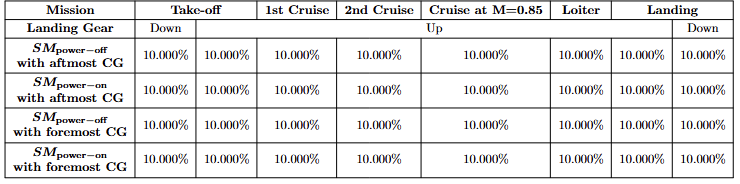 

SM_off_aft * 100

ans =     9.0318    9.2137   12.5479    6.0402   12.2772    3.5317    9.2771    9.0951


SM_on_aft = SM_off_aft  - 0.02;
SM_on_aft * 100

ans =     7.0318    7.2137   10.5479    4.0402   10.2772    1.5317    7.2771    7.0951



SM_off_for * 100

ans =    25.2381   26.1019   29.4361   22.9285   29.1654   20.4199   26.1653   25.3015


SM_on_for = SM_off_for  - 0.02;
SM_on_for * 100

ans =    23.2381   24.1019   27.4361   20.9285   27.1654   18.4199   24.1653   23.3015


## 3. Trim Analysis

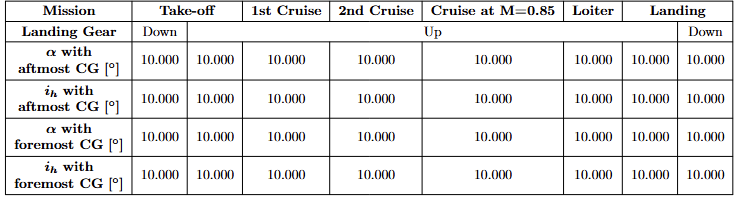

 

 


$$C_L ={\left(C_L \right)}_{w\;} +\eta_h \frac{S_h }{S_w }{\left(C_L \right)}_h$$


**Takeoff**

aftmost (Geardown)

syms alpha i_h

% Define the equations

eqCL = ...
    d_CL_w_TO * (alpha + i_w - a_0_w_TO) + ...
    n_h * (S_h / S_w) * d_CL_h_TO * ((alpha + i_w - a_0_w_TO) * (1 - d_downwash_TO) + (i_h - i_w) - (a_0_h_TO - a_0_w_TO)) - ...
    (W_CG_aft_down * g) / (0.5 * rho_TO * (V_TO ^ 2) * S_w);

eqCM = ...
    (d_CL_w_TO * (alpha + i_w - a_0_w_TO)) * ((x_CG_aft_down - x_ac_w_TO) / c) + ...
    C_m0_w_TO + ...
    d_CM_f * alpha + ...
    n_h * d_CL_h_TO * ((alpha + i_w - a_0_w_TO) * (1 - d_downwash_TO) + (i_h - i_w) - (a_0_h_TO - a_0_w_TO)) * (S_h / S_w) * ((x_CG_aft_down - x_ac_h_TO) / c) + ...
    (-Z_t + z_CG_aft_down) * CD_TO / c;

% Solve the equations symbolically
sol = solve([eqCL == 0, eqCM == 0], [alpha, i_h]);

% Extract solutions for x and y
alpha_TO_aft_down = double(sol.alpha);
alpha_TO_aft_down = rad2deg(alpha_TO_aft_down)

alpha_TO_aft_down = 14.6632

i_h_TO_aft_down = double(sol.i_h);
i_h_TO_aft_down = rad2deg(i_h_TO_aft_down)

i_h_TO_aft_down = -8.8908

aftmost

syms alpha i_h

% Define the equations

eqCL = ...
    d_CL_w_TO * (alpha + i_w - a_0_w_TO) + ...
    n_h * (S_h / S_w) * d_CL_h_TO * ((alpha + i_w - a_0_w_TO) * (1 - d_downwash_TO) + (i_h - i_w) - (a_0_h_TO - a_0_w_TO)) - ...
    (W_CG_aft * g) / (0.5 * rho_TO * (V_TO ^ 2) * S_w);

eqCM = ...
    (d_CL_w_TO * (alpha + i_w - a_0_w_TO)) * ((x_CG_aft - x_ac_w_TO) / c) + ...
    C_m0_w_TO + ...
    d_CM_f * alpha + ...
    n_h * d_CL_h_TO * ((alpha + i_w - a_0_w_TO) * (1 - d_downwash_TO) + (i_h - i_w) - (a_0_h_TO - a_0_w_TO)) * (S_h / S_w) * ((x_CG_aft - x_ac_h_TO) / c) + ...
    (-Z_t + z_CG_aft) * CD_TO / c;

% Solve the equations symbolically
sol = solve([eqCL == 0, eqCM == 0], [alpha, i_h]);

% Extract solutions for x and y
alpha_TO_aft = double(sol.alpha);
alpha_TO_aft = rad2deg(alpha_TO_aft)

alpha_TO_aft = 14.6617

i_h_TO_aft = double(sol.i_h);
i_h_TO_aft = rad2deg(i_h_TO_aft)

i_h_TO_aft = -8.8728

foremost (Geardown)

syms alpha i_h

% Define the equations

eqCL = ...
    d_CL_w_TO * (alpha + i_w - a_0_w_TO) + ...
    n_h * (S_h / S_w) * d_CL_h_TO * ((alpha + i_w - a_0_w_TO) * (1 - d_downwash_TO) + (i_h - i_w) - (a_0_h_TO - a_0_w_TO)) - ...
    (W_CG_for_down * g) / (0.5 * rho_TO * (V_TO ^ 2) * S_w);

eqCM = ...
    (d_CL_w_TO * (alpha + i_w - a_0_w_TO)) * ((x_CG_for_down - x_ac_w_TO) / c) + ...
    C_m0_w_TO + ...
    d_CM_f * alpha + ...
    n_h * d_CL_h_TO * ((alpha + i_w - a_0_w_TO) * (1 - d_downwash_TO) + (i_h - i_w) - (a_0_h_TO - a_0_w_TO)) * (S_h / S_w) * ((x_CG_for_down - x_ac_h_TO) / c) + ...
    (-Z_t + z_CG_for_down) * CD_TO / c;

% Solve the equations symbolically
sol = solve([eqCL == 0, eqCM == 0], [alpha, i_h]);

% Extract solutions for x and y
alpha_TO_for_down = double(sol.alpha);
alpha_TO_for_down = rad2deg(alpha_TO_for_down)

alpha_TO_for_down = 29.6685

i_h_TO_for_down = double(sol.i_h);
i_h_TO_for_down = rad2deg(i_h_TO_for_down)

i_h_TO_for_down = -28.4104

foremost

syms alpha i_h

% Define the equations

eqCL = ...
    d_CL_w_TO * (alpha + i_w - a_0_w_TO) + ...
    n_h * (S_h / S_w) * d_CL_h_TO * ((alpha + i_w - a_0_w_TO) * (1 - d_downwash_TO) + (i_h - i_w) - (a_0_h_TO - a_0_w_TO)) - ...
    (W_CG_for * g) / (0.5 * rho_TO * (V_TO ^ 2) * S_w);

eqCM = ...
    (d_CL_w_TO * (alpha + i_w - a_0_w_TO)) * ((x_CG_for - x_ac_w_TO) / c) + ...
    C_m0_w_TO + ...
    d_CM_f * alpha + ...
    n_h * d_CL_h_TO * ((alpha + i_w - a_0_w_TO) * (1 - d_downwash_TO) + (i_h - i_w) - (a_0_h_TO - a_0_w_TO)) * (S_h / S_w) * ((x_CG_for - x_ac_h_TO) / c) + ...
    (-Z_t + z_CG_for) * CD_TO / c;

% Solve the equations symbolically
sol = solve([eqCL == 0, eqCM == 0], [alpha, i_h]);

% Extract solutions for x and y
alpha_TO_for = double(sol.alpha);
alpha_TO_for = rad2deg(alpha_TO_for)

alpha_TO_for = 29.0954

i_h_TO_for = double(sol.i_h);
i_h_TO_for = rad2deg(i_h_TO_for)

i_h_TO_for = -28.6989

**1st Cruise**

aftmost

syms alpha i_h

% Define the equations

eqCL = ...
    d_CL_w_c1 * (alpha + i_w - a_0_w_c1) + ...
    n_h * (S_h / S_w) * d_CL_h_c1 * ((alpha + i_w - a_0_w_c1) * (1 - d_downwash_c1) + (i_h - i_w) - (a_0_h_c1 - a_0_w_c1)) - ...
    (W_CG_aft * g) / (0.5 * rho_c1 * (V_c1 ^ 2) * S_w);

eqCM = ...
    (d_CL_w_c1 * (alpha + i_w - a_0_w_c1)) * ((x_CG_aft - x_ac_w_c1) / c) + ...
    C_m0_w_c1 + ...
    d_CM_f * alpha + ...
    n_h * d_CL_h_c1 * ((alpha + i_w - a_0_w_c1) * (1 - d_downwash_c1) + (i_h - i_w) - (a_0_h_c1 - a_0_w_c1)) * (S_h / S_w) * ((x_CG_aft - x_ac_h_c1) / c) + ...
    (-Z_t + z_CG_aft) * CD_c1 / c;

% Solve the equations symbolically
sol = solve([eqCL == 0, eqCM == 0], [alpha, i_h]);

% Extract solutions for x and y
alpha_c1_aft = double(sol.alpha);
alpha_c1_aft = rad2deg(alpha_c1_aft)

alpha_c1_aft = 0.9422

i_h_C1_aft = double(sol.i_h);
i_h_C1_aft = rad2deg(i_h_C1_aft)

i_h_C1_aft = -6.1811

foremost 

syms alpha i_h

% Define the equations

eqCL = ...
    d_CL_w_c1 * (alpha + i_w - a_0_w_c1) + ...
    n_h * (S_h / S_w) * d_CL_h_c1 * ((alpha + i_w - a_0_w_c1) * (1 - d_downwash_c1) + (i_h - i_w) - (a_0_h_c1 - a_0_w_c1)) - ...
    (W_CG_for * g) / (0.5 * rho_c1 * (V_c1 ^ 2) * S_w);

eqCM = ...
    (d_CL_w_c1 * (alpha + i_w - a_0_w_c1)) * ((x_CG_for - x_ac_w_c1) / c) + ...
    C_m0_w_c1 + ...
    d_CM_f * alpha + ...
    n_h * d_CL_h_c1 * ((alpha + i_w - a_0_w_c1) * (1 - d_downwash_c1) + (i_h - i_w) - (a_0_h_c1 - a_0_w_c1)) * (S_h / S_w) * ((x_CG_for - x_ac_h_c1) / c) + ...
    (-Z_t + z_CG_for) * CD_c1 / c;

% Solve the equations symbolically
sol = solve([eqCL == 0, eqCM == 0], [alpha, i_h]);

% Extract solutions for x and y
alpha_c1_for = double(sol.alpha);
alpha_c1_for = rad2deg(alpha_c1_for )

alpha_c1_for = 3.0968

i_h_C1_for = double(sol.i_h);
i_h_C1_for = rad2deg(i_h_C1_for)

i_h_C1_for = -8.9932

**2nd Cruise**

aftmost

syms alpha i_h

% Define the equations

eqCL = ...
    d_CL_w_c2 * (alpha + i_w - a_0_w_c2) + ...
    n_h * (S_h / S_w) * d_CL_h_c2 * ((alpha + i_w - a_0_w_c2) * (1 - d_downwash_c2) + (i_h - i_w) - (a_0_h_c2 - a_0_w_c2)) - ...
    (W_CG_aft * g) / (0.5 * rho_c2 * (V_c2 ^ 2) * S_w);

eqCM = ...
    (d_CL_w_c2 * (alpha + i_w - a_0_w_c2)) * ((x_CG_aft - x_ac_w_c2) / c) + ...
    C_m0_w_c2 + ...
    d_CM_f * alpha + ...
    n_h * d_CL_h_c2  * ((alpha + i_w - a_0_w_c2) * (1 - d_downwash_c2) + (i_h - i_w) - (a_0_h_c2 - a_0_w_c2)) * (S_h / S_w) * ((x_CG_aft - x_ac_h_c2) / c) + ...
    (-Z_t + z_CG_aft) * CD_c2 / c;

% Solve the equations symbolically
sol = solve([eqCL == 0, eqCM == 0], [alpha, i_h]);

% Extract solutions for x and y
alpha_c2_aft = double(sol.alpha);
alpha_c2_aft = rad2deg(alpha_c2_aft)

alpha_c2_aft = 1.0359

i_h_C2_aft = double(sol.i_h);
i_h_C2_aft = rad2deg(i_h_C2_aft)

i_h_C2_aft = -5.7638

foremost

syms alpha i_h

% Define the equations

eqCL = ...
    d_CL_w_c2 * (alpha + i_w - a_0_w_c2) + ...
    n_h * (S_h / S_w) * d_CL_h_c2 * ((alpha + i_w - a_0_w_c2) * (1 - d_downwash_c2) + (i_h - i_w) - (a_0_h_c2 - a_0_w_c2)) - ...
    (W_CG_for * g) / (0.5 * rho_c2 * (V_c2 ^ 2) * S_w);

eqCM = ...
    (d_CL_w_c2 * (alpha + i_w - a_0_w_c2)) * ((x_CG_for - x_ac_w_c2) / c) + ...
    C_m0_w_c2 + ...
    d_CM_f * alpha + ...
    n_h * d_CL_h_c2  * ((alpha + i_w - a_0_w_c2) * (1 - d_downwash_c2) + (i_h - i_w) - (a_0_h_c2 - a_0_w_c2)) * (S_h / S_w) * ((x_CG_for - x_ac_h_c2) / c) + ...
    (-Z_t + z_CG_for) * CD_c2 / c;

% Solve the equations symbolically
sol = solve([eqCL == 0, eqCM == 0], [alpha, i_h]);

% Extract solutions for x and y
alpha_c2_for = double(sol.alpha);
alpha_c2_for = rad2deg(alpha_c2_for)

alpha_c2_for = 3.2719

i_h_C2_for = double(sol.i_h);
i_h_C2_for = rad2deg(i_h_C2_for)

i_h_C2_for = -8.3822

**Cruise at M=0.85**

aftmost

syms alpha i_h

% Define the equations

eqCL = ...
    d_CL_w_cmax * (alpha + i_w - a_0_w_cmax) + ...
    n_h * (S_h / S_w) * d_CL_h_cmax * ((alpha + i_w - a_0_w_cmax) * (1 - d_downwash_cmax) + (i_h - i_w) - (a_0_h_cmax - a_0_w_cmax)) - ...
    (W_CG_aft * g) / (0.5 * rho_cmax * (V_cmax ^ 2) * S_w);

eqCM = ...
    (d_CL_w_cmax * (alpha + i_w - a_0_w_cmax)) * ((x_CG_aft - x_ac_w_cmax) / c) + ...
    C_m0_w_cmax + ...
    d_CM_f * alpha + ...
    n_h * d_CL_h_cmax  * ((alpha + i_w - a_0_w_cmax) * (1 - d_downwash_cmax) + (i_h - i_w) - (a_0_h_cmax - a_0_w_cmax)) * (S_h / S_w) * ((x_CG_aft - x_ac_h_cmax) / c) + ...
    (-Z_t + z_CG_aft) * CD_cmax / c;

% Solve the equations symbolically
sol = solve([eqCL == 0, eqCM == 0], [alpha, i_h]);

% Extract solutions for x and y
alpha_cmax_aft = double(sol.alpha);
alpha_cmax_aft = rad2deg(alpha_cmax_aft)

alpha_cmax_aft = 0.5830

i_h_Cmax_aft = double(sol.i_h);
i_h_Cmax_aft = rad2deg(i_h_Cmax_aft)

i_h_Cmax_aft = -5.9805

foremost

syms alpha i_h

% Define the equations

eqCL = ...
    d_CL_w_cmax * (alpha + i_w - a_0_w_cmax) + ...
    n_h * (S_h / S_w) * d_CL_h_cmax * ((alpha + i_w - a_0_w_cmax) * (1 - d_downwash_cmax) + (i_h - i_w) - (a_0_h_cmax - a_0_w_cmax)) - ...
    (W_CG_for * g) / (0.5 * rho_cmax * (V_cmax ^ 2) * S_w);

eqCM = ...
    (d_CL_w_cmax * (alpha + i_w - a_0_w_cmax)) * ((x_CG_for - x_ac_w_cmax) / c) + ...
    C_m0_w_cmax + ...
    d_CM_f * alpha + ...
    n_h * d_CL_h_cmax  * ((alpha + i_w - a_0_w_cmax) * (1 - d_downwash_cmax) + (i_h - i_w) - (a_0_h_cmax - a_0_w_cmax)) * (S_h / S_w) * ((x_CG_for - x_ac_h_cmax) / c) + ...
    (-Z_t + z_CG_for) * CD_cmax / c;

% Solve the equations symbolically
sol = solve([eqCL == 0, eqCM == 0], [alpha, i_h]);

% Extract solutions for x and y
alpha_cmax_for = double(sol.alpha);
alpha_cmax_for = rad2deg(alpha_cmax_for)

alpha_cmax_for = 2.4515

i_h_Cmax_for = double(sol.i_h);
i_h_Cmax_for = rad2deg(i_h_Cmax_for)

i_h_Cmax_for = -8.3837

**Loiter**

aftmost

syms alpha i_h

% Define the equations

eqCL = ...
    d_CL_w_loi * (alpha + i_w - a_0_w_loi) + ...
    n_h * (S_h / S_w) * d_CL_h_loi * ((alpha + i_w - a_0_w_loi) * (1 - d_downwash_loi) + (i_h - i_w) - (a_0_h_loi - a_0_w_loi)) - ...
    (W_CG_aft * g) / (0.5 * rho_loi * (V_loi ^ 2) * S_w);

eqCM = ...
    (d_CL_w_loi * (alpha + i_w - a_0_w_loi)) * ((x_CG_aft - x_ac_w_loi) / c) + ...
    C_m0_w_loi + ...
    d_CM_f * alpha + ...
    n_h * d_CL_h_loi * ((alpha + i_w - a_0_w_loi) * (1 - d_downwash_loi) + (i_h - i_w) - (a_0_h_loi - a_0_w_loi)) * (S_h / S_w) * ((x_CG_aft - x_ac_h_loi) / c) + ...
    (-Z_t + z_CG_aft) * CD_loi / c;

% Solve the equations symbolically
sol = solve([eqCL == 0, eqCM == 0], [alpha, i_h]);

% Extract solutions for x and y
alpha_loi_aft = double(sol.alpha);
alpha_loi_aft = rad2deg(alpha_loi_aft)

alpha_loi_aft = 2.6354

i_h_L_aft = double(sol.i_h);
i_h_L_aft = rad2deg(i_h_L_aft)

i_h_L_aft = -5.7610

foremost

syms alpha i_h

% Define the equations

eqCL = ...
    d_CL_w_loi * (alpha + i_w - a_0_w_loi) + ...
    n_h * (S_h / S_w) * d_CL_h_loi * ((alpha + i_w - a_0_w_loi) * (1 - d_downwash_loi) + (i_h - i_w) - (a_0_h_loi - a_0_w_loi)) - ...
    (W_CG_for * g) / (0.5 * rho_loi * (V_loi ^ 2) * S_w);

eqCM = ...
    (d_CL_w_loi * (alpha + i_w - a_0_w_loi)) * ((x_CG_for - x_ac_w_loi) / c) + ...
    C_m0_w_loi + ...
    d_CM_f * alpha + ...
    n_h * d_CL_h_loi * ((alpha + i_w - a_0_w_loi) * (1 - d_downwash_loi) + (i_h - i_w) - (a_0_h_loi - a_0_w_loi)) * (S_h / S_w) * ((x_CG_for - x_ac_h_loi) / c) + ...
    (-Z_t + z_CG_for) * CD_loi / c;

% Solve the equations symbolically
sol = solve([eqCL == 0, eqCM == 0], [alpha, i_h]);

% Extract solutions for x and y
alpha_loi_for = double(sol.alpha);
alpha_loi_for = rad2deg(alpha_loi_for)

alpha_loi_for = 6.1529

i_h_loi_for = double(sol.i_h);
i_h_loi_for = rad2deg(i_h_loi_for)

i_h_loi_for = -9.7384

**Landing**

aftmost

syms alpha i_h

% Define the equations

eqCL = ...
    d_CL_w_L * (alpha + i_w - a_0_w_L) + ...
    n_h * (S_h / S_w) * d_CL_h_L * ((alpha + i_w - a_0_w_L) * (1 - d_downwash_L) + (i_h - i_w) - (a_0_h_L - a_0_w_L)) - ...
    (W_CG_aft * g) / (0.5 * rho_L * (V_L ^ 2) * S_w);

eqCM = ...
    (d_CL_w_L * (alpha + i_w - a_0_w_L)) * ((x_CG_aft - x_ac_w_L) / c) + ...
    C_m0_w_L + ...
    d_CM_f * alpha + ...
    n_h * d_CL_h_L * ((alpha + i_w - a_0_w_L) * (1 - d_downwash_L) + (i_h - i_w) - (a_0_h_L - a_0_w_L)) * (S_h / S_w) * ((x_CG_aft - x_ac_h_L) / c) + ...
    (-Z_t + z_CG_aft) * CD_L / c;

% Solve the equations symbolically
sol = solve([eqCL == 0, eqCM == 0], [alpha, i_h]);

% Extract solutions for x and y
alpha_L_aft = double(sol.alpha);
alpha_L_aft = rad2deg(alpha_L_aft)

alpha_L_aft = 10.3849

i_h_L_aft = double(sol.i_h);
i_h_L_aft = rad2deg(i_h_L_aft)

i_h_L_aft = -7.8985

aftmost (Geardown)

syms alpha i_h

% Define the equations

eqCL = ...
    d_CL_w_L * (alpha + i_w - a_0_w_L) + ...
    n_h * (S_h / S_w) * d_CL_h_L * ((alpha + i_w - a_0_w_L) * (1 - d_downwash_L) + (i_h - i_w) - (a_0_h_L - a_0_w_L)) - ...
    (W_CG_aft_down * g) / (0.5 * rho_L * (V_L ^ 2) * S_w);

eqCM = ...
    (d_CL_w_L * (alpha + i_w - a_0_w_L)) * ((x_CG_aft_down - x_ac_w_L) / c) + ...
    C_m0_w_L + ...
    d_CM_f * alpha + ...
    n_h * d_CL_h_L * ((alpha + i_w - a_0_w_L) * (1 - d_downwash_L) + (i_h - i_w) - (a_0_h_L - a_0_w_L)) * (S_h / S_w) * ((x_CG_aft_down - x_ac_h_L) / c) + ...
    (-Z_t + z_CG_aft_down) * CD_L / c;

% Solve the equations symbolically
sol = solve([eqCL == 0, eqCM == 0], [alpha, i_h]);

% Extract solutions for x and y
alpha_L_aft_down = double(sol.alpha);
alpha_L_aft_down = rad2deg(alpha_L_aft_down)

alpha_L_aft_down = 10.3926

i_h_L_aft_down = double(sol.i_h);
i_h_L_aft_down = rad2deg(i_h_L_aft_down)

i_h_L_aft_down = -7.9938

foremost

syms alpha i_h

% Define the equations

eqCL = ...
    d_CL_w_L * (alpha + i_w - a_0_w_L) + ...
    n_h * (S_h / S_w) * d_CL_h_L * ((alpha + i_w - a_0_w_L) * (1 - d_downwash_L) + (i_h - i_w) - (a_0_h_L - a_0_w_L)) - ...
    (W_CG_for * g) / (0.5 * rho_L * (V_L ^ 2) * S_w);

eqCM = ...
    (d_CL_w_L * (alpha + i_w - a_0_w_L)) * ((x_CG_for - x_ac_w_L) / c) + ...
    C_m0_w_L + ...
    d_CM_f * alpha + ...
    n_h * d_CL_h_L * ((alpha + i_w - a_0_w_L) * (1 - d_downwash_L) + (i_h - i_w) - (a_0_h_L - a_0_w_L)) * (S_h / S_w) * ((x_CG_for - x_ac_h_L) / c) + ...
    (-Z_t + z_CG_for) * CD_L / c;

% Solve the equations symbolically
sol = solve([eqCL == 0, eqCM == 0], [alpha, i_h]);

% Extract solutions for x and y
alpha_L_for = double(sol.alpha);
alpha_L_for = rad2deg(alpha_L_for)

alpha_L_for = 22.2179

i_h_L_for = double(sol.i_h);
i_h_L_for = rad2deg(i_h_L_for)

i_h_L_for = -24.3326

foremost (Geardown)

syms alpha i_h

% Define the equations

eqCL = ...
    d_CL_w_L * (alpha + i_w - a_0_w_L) + ...
    n_h * (S_h / S_w) * d_CL_h_L * ((alpha + i_w - a_0_w_L) * (1 - d_downwash_L) + (i_h - i_w) - (a_0_h_L - a_0_w_L)) - ...
    (W_CG_for_down * g) / (0.5 * rho_L * (V_L ^ 2) * S_w);

eqCM = ...
    (d_CL_w_L * (alpha + i_w - a_0_w_L)) * ((x_CG_for_down - x_ac_w_L) / c) + ...
    C_m0_w_L + ...
    d_CM_f * alpha + ...
    n_h * d_CL_h_L * ((alpha + i_w - a_0_w_L) * (1 - d_downwash_L) + (i_h - i_w) - (a_0_h_L - a_0_w_L)) * (S_h / S_w) * ((x_CG_for_down - x_ac_h_L) / c) + ...
    (-Z_t + z_CG_for_down) * CD_L / c;

% Solve the equations symbolically
sol = solve([eqCL == 0, eqCM == 0], [alpha, i_h]);

% Extract solutions for x and y
alpha_L_for_down = double(sol.alpha);
alpha_L_for_down = rad2deg(alpha_L_for_down)

alpha_L_for_down = 22.6914

i_h_L_for_down = double(sol.i_h);
i_h_L_for_down = rad2deg(i_h_L_for_down)

i_h_L_for_down = -24.1388